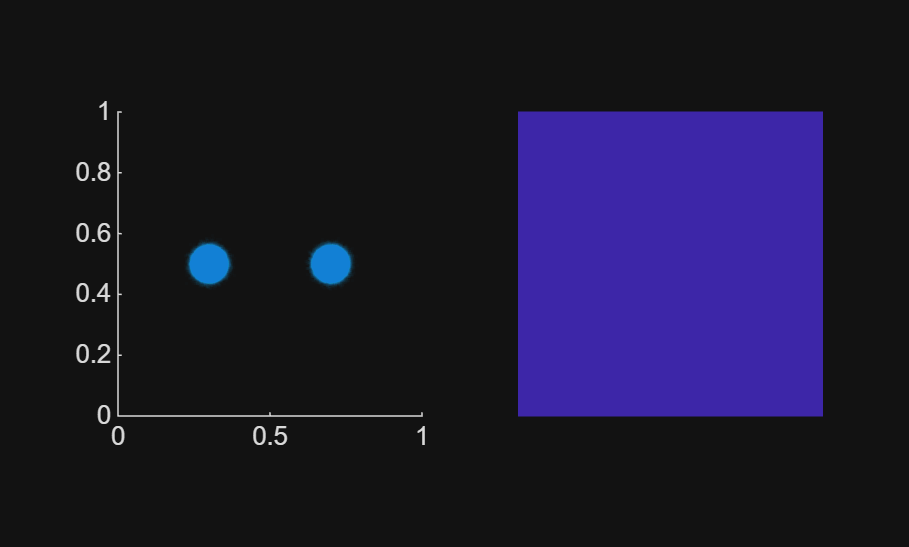

NumP = 3000000;
dt = .0005;
SpR = 200;
alpha = .3;

R  = mvnrnd([.5 .3],eye(2)*.0003,NumP*1/2);
V  = [-R(:,2) R(:,1)]*1+[-5 0];

R1 = mvnrnd([.5 .7],eye(2)*.0003,NumP*1/2);
V1 = [-R(:,2) R(:,1)]*1+[ 5 0];

R =  ([R;R1]);
V =  ([V;V1]);

R = mod(R,1);

subplot(1,2,1)
b = gpuArray(accumarray(ceil(SpR*R),ones([size(R,1) 1]),[SpR SpR]));
% Ip = imshow(rho,InitialMagnification=100);
Sp = scatter(R(:,2),R(:,1),1,'.','MarkerEdgeAlpha',.01);
xlim([0 1])
ylim([0 1])
axis square
subplot(1,2,2)
% Lp = plot([0],[0],'r',[0],[0],'g',[0],[0],'y',[0],[0],'w');
I = imshow(mat2gray(flipud(b.*0)),InitialMagnification=100);
hold on
colormap parula;

drawnow;

psi = gpuArray(0*b);
Err = gpuArray(b-imfilter(psi,fspecial("laplacian"),"circular","conv"));
psi = psi-alpha*(Err);
Errl = gpuArray(Err);
Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
psi = psi-alpha*(Err);
    for j = 1:6000
    Errl = Err;
    Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
    psi = psi-alpha*(Err);
    Ep = sum(sum(abs(Errl-Err)));
    alpha = (.3*Ep+3)/(Ep+1);
    end
    bCS = accumarray(ceil(SpR*R),ones([size(R,1) 1]),[SpR SpR],[],[],true);
    IndR = (sub2ind(size(psi),ceil(SpR*(R(:,1))),ceil(SpR*(R(:,2)))));
    Vmx = (accumarray(ceil(SpR*R),V(:,1),[SpR SpR],[],[],true)./bCS);
    Vmy = (accumarray(ceil(SpR*R),V(:,2),[SpR SpR],[],[],true)./bCS);
    Tstd = (accumarray(ceil(SpR*R),(V(:,1)-Vmx(IndR)).^2+(V(:,2)-Vmy(IndR)).^2,[SpR SpR],[],[],true));
    Tstd = (Tstd>0).*(imfilter(Tstd,ones(11),'conv')./imfilter(1.*full(Tstd>0),ones(11),'conv'));

Error using matlab.internal.math.imfilter
Sparse matrices are not supported.
Error in imfilter (line 3)
b = matlab.internal.math.imfilter(args{:});
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

    Tstd = .5*(sqrt(Tstd./bCS));
    % Tstd = fillmissing(Tstd, 'constant', 0);
    bg = imgaussfilt(b,2,padding="circular");
    [PrBDx1,PrBDy1] = spGradI(bg,ceil(SpR*(R)),SpR);
    MB = 0;

for i=1:3000
    for j = 1:1000
    Errl = Err;
    Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
    psi = psi-alpha*(Err);
    Ep = sum(sum(abs(Errl-Err)));
    alpha = (.3*Ep+3)/(Ep+1);
    end
    [psiDx,psiDy] = spGradI(psi,ceil(SpR*(R)),SpR);
    % [PrBDx,PrBDy] = gradient(b);

    IndR = sub2ind(size(psi),ceil(SpR*(R(:,1))),ceil(SpR*(R(:,2))));
    V = [Vmx(IndR) Vmy(IndR)] ...
        + mvnrnd([0 0],eye(2),NumP).*Tstd(IndR) ...
        - gather(dt.*[psiDx psiDy]*.1) ...
        - gather(dt.*[PrBDx1 PrBDy1].*2);
    R = R + dt.*V;
    R = mod(R,1);
    bCS = accumarray(ceil(SpR*R),ones([size(R,1) 1]),[SpR SpR],[],[],true);
    b = bCS;
    IndR = sub2ind(size(psi),ceil(SpR*(R(:,1))),ceil(SpR*(R(:,2))));
    Vmx = accumarray(ceil(SpR*R),V(:,1),[SpR SpR],[],[],true)./bCS;
    Vmy = accumarray(ceil(SpR*R),V(:,2),[SpR SpR],[],[],true)./bCS;
    Tstd = accumarray(ceil(SpR*R),(V(:,1)-Vmx(IndR)).^2+(V(:,2)-Vmy(IndR)).^2,[SpR SpR],[],[],true);
    TTE = gather(sum(Tstd,"all","omitmissing")*.5);
    TMV = gather(sum((Vmy.^2+Vmx.^2).*b.^2,"all","omitmissing")*.5);
    TPE = gather(sum(psi(IndR),"all","omitmissing"));
    Tstd = .5*(sqrt(Tstd./bCS));
    bg = imgaussfilt(full(b),1,padding="circular");
    [PrBDx1,PrBDy1] = spGradI(bg,ceil(SpR*(R)),SpR);
    % bg = imgaussfilt(bg,10,padding="circular");
    % [PrBDx2,PrBDy2] = gradient(bg);
    % bg = imgaussfilt(bg,10,padding="circular");
    % [PrBDx3,PrBDy3] = gradient(bg);
    % bg = imgaussfilt(bg,10,padding="circular");
    % [PrBDx4,PrBDy4] = gradient(bg);

    set(Sp,'XData',(R(:,2)),'YData',R(:,1));
    % set(Ip,'CData',.01*(b))
    % set(I,'CData',mat2gray(gather((PrBDx.^2+PrBDy.^2).*b)));
    set(I,'CData',mat2gray(flipud(log(b+1))));
    % set(Lp(1),'XData',[get(Lp(1),'XData') i+1],'YData',[get(Lp(1),'YData') TTE]);
    % set(Lp(2),'XData',[get(Lp(2),'XData') i+1],'YData',[get(Lp(2),'YData') TMV]);
    % set(Lp(3),'XData',[get(Lp(3),'XData') i+1],'YData',[get(Lp(3),'YData') TPE]);
    % set(Lp(4),'XData',[get(Lp(4),'XData') i+1],'YData',[get(Lp(4),'YData') 0  ]);
    drawnow;
end

% function [Gx,Gy]=spGradI(A,P,sz)
% Gx = A(sub2ind(size(A),mod(P(:,1)  ,sz(1)-1)+1,P(:,2)))-A(sub2ind(size(A),mod(P(:,1)-2,sz(1)-1)+1,P(:,2)));
% Gy = A(sub2ind(size(A),P(:,1),mod(P(:,2)  ,sz(1)-1)+1))-A(sub2ind(size(A),P(:,1),mod(P(:,2)-2,sz(1)-1)+1));
% end

function [Gx,Gy]=spGradI(A,P,sz)

X = P(:,1);
Y = P(:,2);
Xm = mod(X-2,sz(1)-1)+1;
Xp = mod(X  ,sz(1)-1)+1;
Ym = mod(Y-2,sz(1)-1)+1;
Yp = mod(Y  ,sz(1)-1)+1;
XmI = sub2ind(size(A),Xm,Y);
XpI = sub2ind(size(A),Xp,Y);
YmI = sub2ind(size(A),X,Ym);
YpI = sub2ind(size(A),X,Yp);

Gx = A(XpI)-A(XmI);
Gy = A(YpI)-A(YmI);
end